clc;clear;

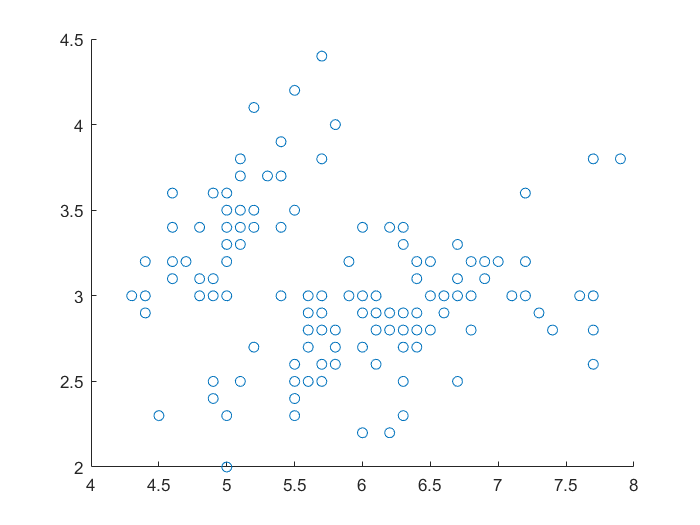

load fisheriris
% We only extract two features for easy visulization
X = meas(:, 1:2);
feature_num = size(X, 2);
scatter(X(:, 1), X(:, 2))

cluster_num = 3;
Xmax = max(X);
Xmin = min(X);
centers = rand([cluster_num feature_num]).*(Xmax-Xmin) + Xmin;

distances = zeros(cluster_num, size(X, 1));
for c=1:cluster_num
    center = centers(c, :);
    distance = sum((X-center).^2, 2);
    distances(c, :) = distance;
end
[~, outcome] = min(distances);

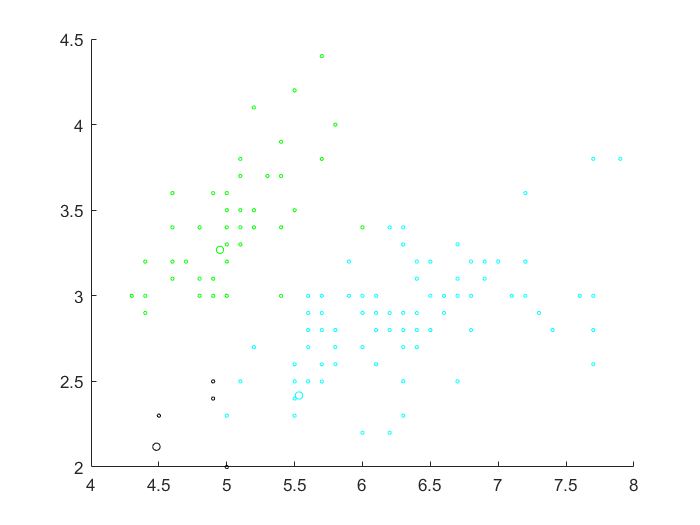

% The larger points are the centers initialized
figure(1);
c1 = outcome == 1;
c2 = outcome == 2;
c3 = outcome == 3;
scatter(X(c1, 1), X(c1, 2), 4, "cyan");
hold on;
scatter(centers(1, 1), centers(1, 2), 20, "cyan");
hold on;
scatter(X(c2, 1), X(c2, 2), 4, "black");
hold on;
scatter(centers(2, 1), centers(2, 2), 20, "black");
hold on;
scatter(X(c3, 1), X(c3, 2), 4, "green");
scatter(centers(3, 1), centers(3, 2), 20, "green")

for c=1:cluster_num
    idx = outcome == c;
    points = X(idx, :);
    centers(c, :) = mean(points)
end

centers =     6.3158    2.8832
    4.4821    2.1185
    4.9501    3.2685


centers =     6.3158    2.8832
    4.8250    2.3000
    4.9501    3.2685


centers =     6.3158    2.8832
    4.8250    2.3000
    5.0431    3.4412


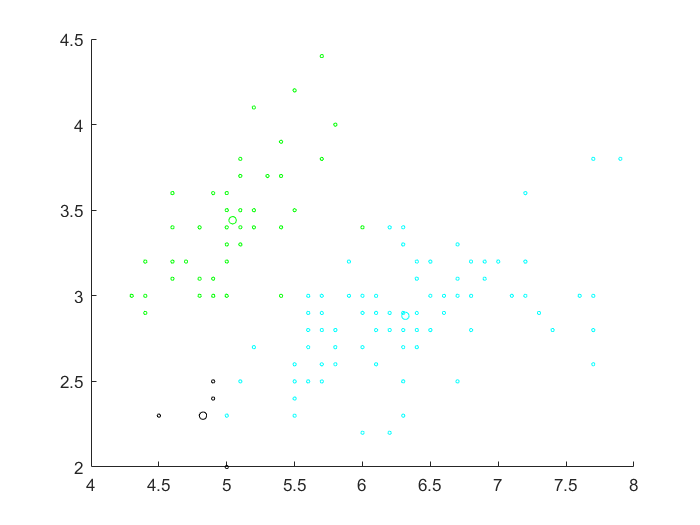

% Visualize the re-centered map
figure(2);
c1 = outcome == 1;
c2 = outcome == 2;
c3 = outcome == 3;
scatter(X(c1, 1), X(c1, 2), 4, "cyan");
hold on;
scatter(centers(1, 1), centers(1, 2), 20, "cyan");
hold on;
scatter(X(c2, 1), X(c2, 2), 4, "black");
hold on;
scatter(centers(2, 1), centers(2, 2), 20, "black");
hold on;
scatter(X(c3, 1), X(c3, 2), 4, "green");
scatter(centers(3, 1), centers(3, 2), 20, "green")
hold off;

distances = zeros(cluster_num, size(X, 1));
for c=1:cluster_num
    center = centers(c, :);
    distance = sum((X-center).^2, 2);
    distances(c, :) = distance;
end
[~, outcome] = min(distances);

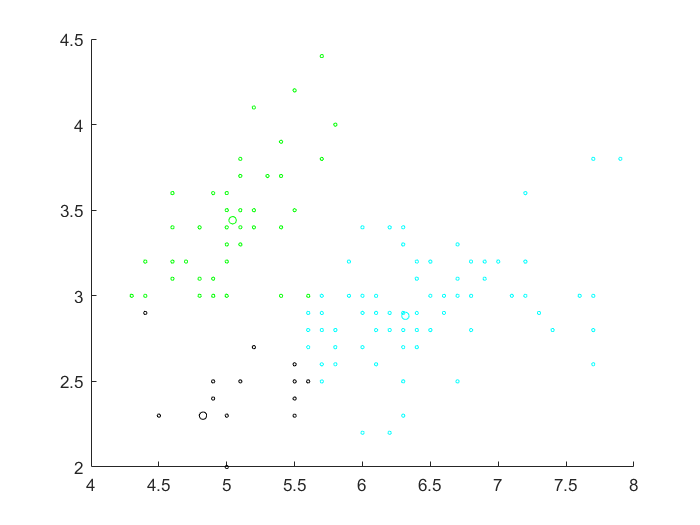

% Visualize the re-centered map
figure(2);
c1 = outcome == 1;
c2 = outcome == 2;
c3 = outcome == 3;
scatter(X(c1, 1), X(c1, 2), 4, "cyan");
hold on;
scatter(centers(1, 1), centers(1, 2), 20, "cyan");
hold on;
scatter(X(c2, 1), X(c2, 2), 4, "black");
hold on;
scatter(centers(2, 1), centers(2, 2), 20, "black");
hold on;
scatter(X(c3, 1), X(c3, 2), 4, "green");
scatter(centers(3, 1), centers(3, 2), 20, "green")
hold off;

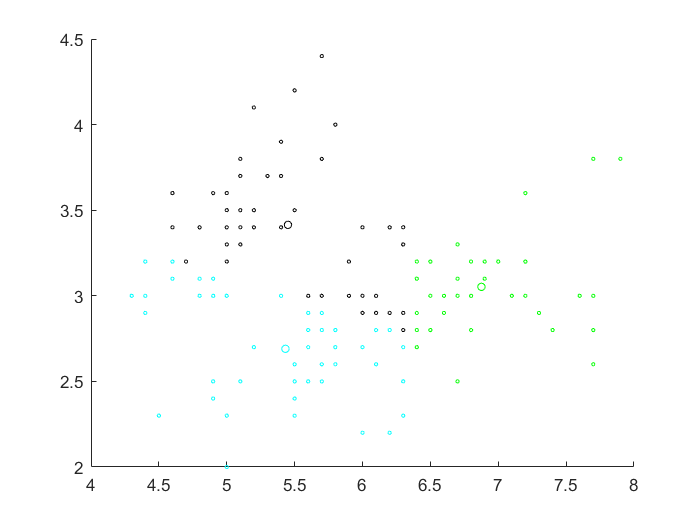

% With the function form
[outcome, centers] = k_means(X, 3);
figure(2);
c1 = outcome == 1;
c2 = outcome == 2;
c3 = outcome == 3;
scatter(X(c1, 1), X(c1, 2), 4, "cyan");
hold on;
scatter(centers(1, 1), centers(1, 2), 20, "cyan");
hold on;
scatter(X(c2, 1), X(c2, 2), 4, "black");
hold on;
scatter(centers(2, 1), centers(2, 2), 20, "black");
hold on;
scatter(X(c3, 1), X(c3, 2), 4, "green");
scatter(centers(3, 1), centers(3, 2), 20, "green")
hold off;